Maximum F = 436.2𝑘𝑁

clear all
clf
N_top = 2.1499e5; %N
M_top = 11.638; %Nm
N_midt = 2.4088e5; %N
M_midt = 85.326; %Nm
N_bot = 2.3954e5; %N
M_bot = 86.191; %Nm

N = [N_top, N_midt, N_bot];
M = [M_top, M_midt, M_bot];
d = 0.024; %m bolt diameter
A_t = 353e-6; %tensile stress area %pi*(d/2)^2
A_test = pi*(d/2)^2

A_test =    0.00045239


S_N1 = N/A_t

S_N1 =    6.0904e+08   6.8238e+08   6.7858e+08



I = pi * d^4 / 64

I =    1.6286e-08


y = d/2; %armen til momentet
S_N2 = M * y / I

S_N2 =    8.5752e+06   6.2871e+07   6.3508e+07



S_max = S_N1 + S_N2

S_max =    6.1761e+08   7.4525e+08   7.4209e+08


Minimum F = 43.6𝑘𝑁

N_top = 2.0714e5; %N
M_top = 2.8462; %Nm
N_midt = 2.0631e5; %N
M_midt = 3.1656; %Nm
N_bot = 2.0675e5; %N
M_bot = 5.7774; %Nm

N = [N_top, N_midt, N_bot];
M = [M_top, M_midt, M_bot];

A_t = 353e-6; %tensile stress area %pi*(d/2)^2
% d = 0.024; %m bolt diameter
d = sqrt(A_t*4/pi)

d =        0.0212


% A_test = pi*(d/2)^2
S_N1 = N/A_t

S_N1 =     5.868e+08   5.8445e+08   5.8569e+08



I = pi * d^4 / 64

I =    9.9161e-09


y = d/2; %armen til momentet
S_N2 = M * y / I

S_N2 =    3.0426e+06    3.384e+06    6.176e+06



S_min = S_N1 + S_N2

S_min =    5.8984e+08   5.8783e+08   5.9187e+08


Stress range $\Delta\sigma$

DS = S_max - S_min %stress range Pa

DS =    2.7771e+07   1.5742e+08   1.5022e+08


Den mest kritiske bolt er midter bolten da den har størst stress range

curve data load 0 to 500kN

% clear all
% clf
% % Define the filename and range
% filename = 'D:\Mathias\OneDrive\Mathias uddannelse\Ingeniør\Maskinteknik\6. Semester\Avanceret udmattelseslære\Opgaver\Opgave 12\Heat exchanger experiments data.xlsx';
% % filename = 'C:\AU onedrive\OneDrive - Aarhus universitet\Varmetransmission\Heat exchanger experiments data.xlsx';
% 
% 
% range = 'G19:L19';
% exp2_test1 = xlsread(filename, range) % Import data from Excel file
clf
F = [0, 100, 200, 300, 400, 500];
N_0 = 2.200e5;	
M_0 = 4.067;
N_100 = 2.056e5;	
M_100 = 2.707;
N_200 = 2.084e5;	
M_200 = 13.26;
N_300 = 2.133e5;	
M_300 = 36.24;
N_400 = 2.348e5;
M_400 = 66.35;
N_500 = 2.550e5;	
M_500 = 119.7

M_500 =         119.7


N = [N_0, N_100, N_200, N_300, N_400, N_500];
M = [M_0, M_100, M_200, M_300, M_400, M_500];

A_t = 353e-6; %tensile stress area %pi*(d/2)^2
% d = 0.024; %m bolt diameter
d = sqrt(A_t*4/pi)

d =        0.0212


% A_test = pi*(d/2)^2
S_N1 = N/A_t

S_N1 =    6.2323e+08   5.8244e+08   5.9037e+08   6.0425e+08   6.6516e+08   7.2238e+08



I = pi * d^4 / 64

I =    9.9161e-09


y = d/2; %armen til momentet
S_N2 = M * y / I

S_N2 =    4.3476e+06   2.8938e+06   1.4175e+07    3.874e+07   7.0927e+07   1.2796e+08



S = S_N1 + S_N2

S =    6.2758e+08   5.8533e+08   6.0454e+08   6.4299e+08   7.3608e+08   8.5034e+08



plot(F,S/1e6,'--o', DisplayName='Stresses from SW test')
hold on
xlabel('Applied total force (kN)')
ylabel('Stress on critical bolt $\sigma$(MPa)', Interpreter='latex')
grid("on")

F_lin = linspace(0,500,100)

F_lin =             0       5.0505       10.101       15.152       20.202       25.253       30.303       35.354       40.404       45.455       50.505       55.556       60.606       65.657       70.707       75.758       80.808       85.859       90.909        95.96       101.01       106.06       111.11       116.16       121.21       126.26       131.31       136.36       141.41       146.46       151.52       156.57       161.62       166.67       171.72       176.77       181.82       186.87       191.92       196.97       202.02       207.07       212.12       217.17       222.22       227.27       232.32       237.37       242.42       247.47


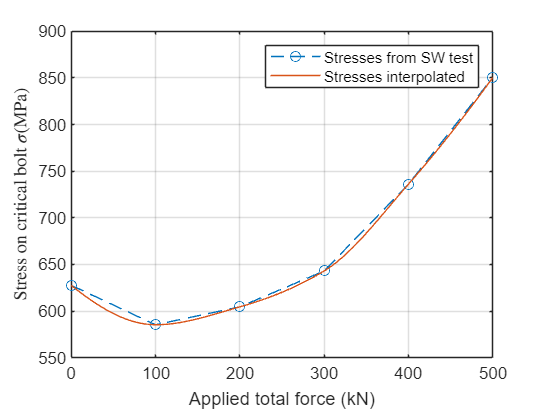

S_lin = interp1(F,S,F_lin, 'pchip');
plot(F_lin,S_lin/1e6, DisplayName='Stresses interpolated')
legend()
hold off


Fs = [43.6, 436.2];
S_int = interp1(F,S,Fs, 'pchip');
S_min_int = S_int(1)

S_min_int =    6.0037e+08


S_max_int = S_int(2)

S_max_int =    7.7484e+08


Finding the life cyles with EC3-1-9 DC50.

N_start = 1e4;
N_DC = 2e6;
dS_DC = 50;
N_D = 5e6;
N_L = 1e8;
m1 = 3;
m2 = 5;

C1 = dS_DC^m1 * N_DC;
syms dS_D_sym
dS_D_eq = C1 == dS_D_sym^m1 * N_D;
dS_D = solve(dS_D_eq, dS_D_sym);
dS_D = double(dS_D(1))

dS_D =         36.84



syms dS_start_sym
dS_start_eq = C1 == dS_start_sym^m1 * N_start;
dS_start = solve(dS_start_eq, dS_start_sym);
dS_start = double(dS_start(1))

dS_start =         292.4



C2 = dS_D^m2 * N_D;

syms dS_L_sym
dS_L_eq = C2 == dS_L_sym^m2 * N_L;
dS_L = solve(dS_L_eq, dS_L_sym);
dS_L = double(dS_L(1))

dS_L =        20.236


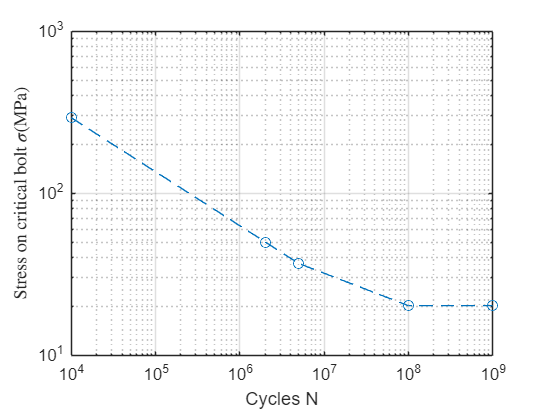


dSs = [dS_start, dS_DC, dS_D, dS_L, dS_L];
Ns = [N_start, N_DC, N_D, N_L, 1e9];

loglog(Ns, dSs,'--o')
xlabel('Cycles N')
ylabel('Stress on critical bolt $\sigma$(MPa)', Interpreter='latex')
ylim([10,1000])
grid("on")

estemated life

format shortg
DS = (S_max - S_min)/1e6; %converting to MPa
% N_life = [];
for i = 1:length(DS)
    if DS(i) > dS_D
        m = m1;
        C = C1;
    else
        m = m2;
        C = C2;
    end
    syms N_sym; assume(N_sym, 'real'); assume(N_sym, 'positive')
    N_eq = C == DS(i)^m * N_sym;
    N = solve(N_eq, N_sym);
    N_life(i) = double(N(1))
end

N_life =    2.0543e+07


N_life =    2.0543e+07        64087


N_life =    2.0543e+07        64087        73747



N_life_top = N_life(1)

N_life_top =    2.0543e+07


N_life_midt = N_life(2)

N_life_midt =         64087


N_life_bot = N_life(3)

N_life_bot =         73747


b) The structure was tested and endured 169.800 load cycles before the bolts fractured under the

above load [1]. Compare your calculations with this value.

It would not hold then since i got less then half the cyles, my estimate is very conservative

c) Create a plot of the bolt stress as a function of the external load in the range 𝐹 = 0 − 500𝑘𝑁 for

the critical bolt and explain how you could use this nonlinear transfer function for VA loading.